load p0Workspace.mat

load pdat.mat

p = pulses(1)

p = struct with fields:
       pTim: [5×1 double]
    mAmpInt: [5×2 double]
     mAmpMx: [5×2 double]
      fname: '160805_145525'
      dWid1: [1564×1 uint16]
      dWid2: 0
      vAng1: [1564×1 double]
      vAng2: 0
      hAng1: [1564×1 double]
      hAng2: 0
     color1: [1×1564 double]
     color2: [1×1564 double]


tims = uint64(p.pTim)

tims = 5×1 uint64 column vector
   83800
   84156
   85425
   85846
   86914


tims = (tims*144/1e4)

tims = 5×1 uint64 column vector
   1207
   1212
   1230
   1236
   1252


wids = p.dWid1(tims)

wids = 5×1 uint16 column vector
   70
   66
   66
   70
   74


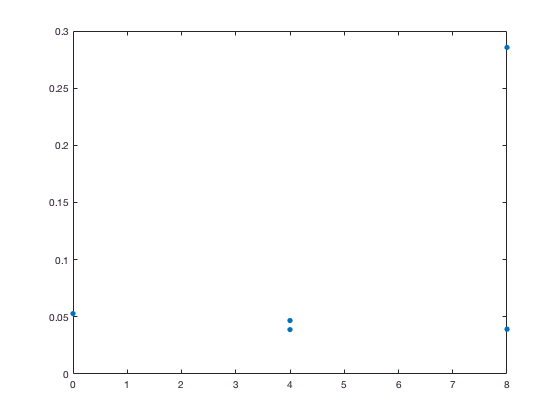

plot(max(wids)-wids, p.mAmpMx(:,1), '.', 'MarkerSize', 15)

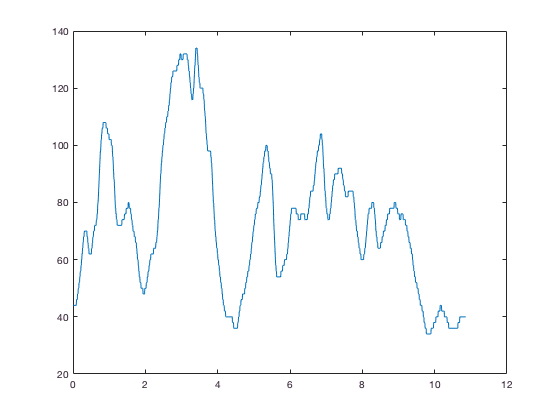

plot((1:length(p.dWid1))/144, p.dWid1)

npulses = 0;
nwids = 0

nwids = 0


for i=1:length(pulses)
    npulses=npulses+length(pulses(i).pTim);
    nwids = nwids + length(pulses(i).dWid1);
end 

pTims = zeros(npulses,1);
pmAmpMx = zeros(npulses,1);
pmAmpInt = zeros(npulses,1);
pHeight = zeros(npulses, 1);
pWids = zeros(npulses, 1);
pDists = zeros(npulses, 1);
% for i=1:length(pulses)
%     wid = pulses(i).dWid1;
%     b = a+length(wid)-1;
%     pWids(a:b,:) = wid;
%     a = b;
% end 

a=1;
for i=1:length(pulses)
   p = pulses(i);
   ampmx = p.mAmpMx;

   tim = uint64(p.pTim)*144/1e4; 
   b = a+length(tim)-1;

   pTims(a:b,:) = tim;
   if max(tim) <= sizewid(1)
       dwid = p.dWid1(tim)/2;
       pWids(a:b,:) = dwid;
       
       % Right now the calculation will be from 
       % the fly to the object on the screen. 
       scrDismm = 100;
       theta = atan2(double(dwid), double(scrDismm)); %100mm from fly to screen

       D = double(scrDismm)./cos(theta);
       pDists(a:b,:) = D-scrDismm;
   end
   
   pmAmpMx(a:b,:) = ampmx(:,2);
   pmAmpInt(a:b,:) = p.mAmpInt(:,2);
   a = b;
end

xs = pDists(pDists ~=0)';
ys = pmAmpInt(pDists ~=0)';

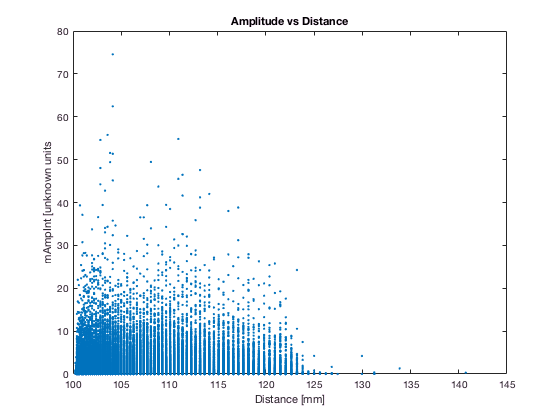

figure
plot(xs, ys, '.');
xlabel('Distance [mm]');
ylabel('mAmpInt [unknown units');
title('Amplitude vs Distance')

histfeatures = [xs; ys]';

size(histfeatures)

ans =        70656           2


histogram = hist3(histfeatures, [10, 10]);

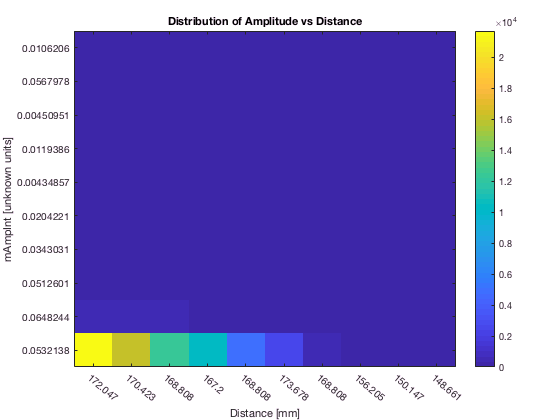

histimage = fliplr(histogram)';
h = imagesc(histimage);

xticklabels(flip(xs));
yticklabels(ys(1:length(ys)-20))
xtickangle(-40);
xlabel('Distance [mm]')
ylabel('mAmpInt [unknown units]')
title('Distribution of Amplitude vs Distance')
colorbar()